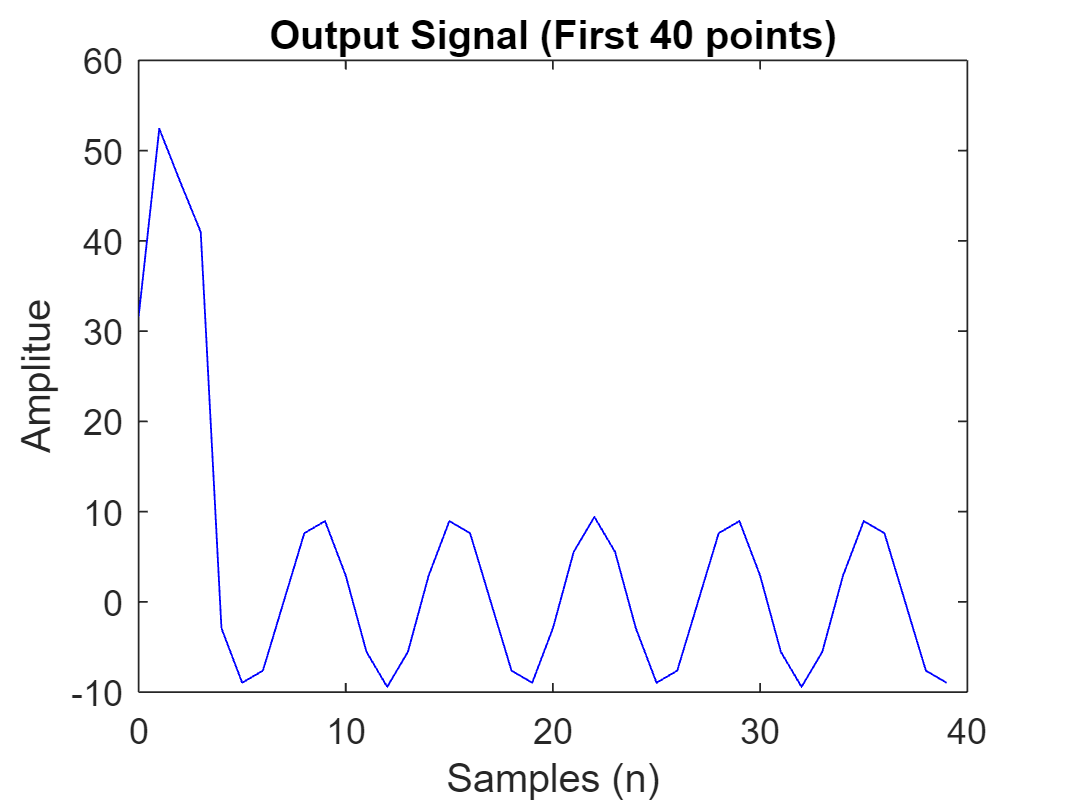

%b. Create inpute signal
n = 0:149;
x = 5*cos(0.3*pi*n) + 22*cos(0.44*pi*n - pi/3) + 22*cos(0.7*pi*n - pi/4);

%c. Apply the two nulling filters in cascade
b1 = [1, -2*cos(0.44*pi), 1]; % Coefficients for 0.44π nulling filter
b2 = [1, -2*cos(0.7*pi), 1]; % Coefficients for 0.7π nulling filter
y1 = firfilt(b1, x);
y2 = firfilt(b2, y1);

%d Plot first 40 points
figure;
plot(n(1:40), y2(1:40), 'b');
title('Output Signal (First 40 points)');
xlabel('Samples (n)');
ylabel('Amplitue');

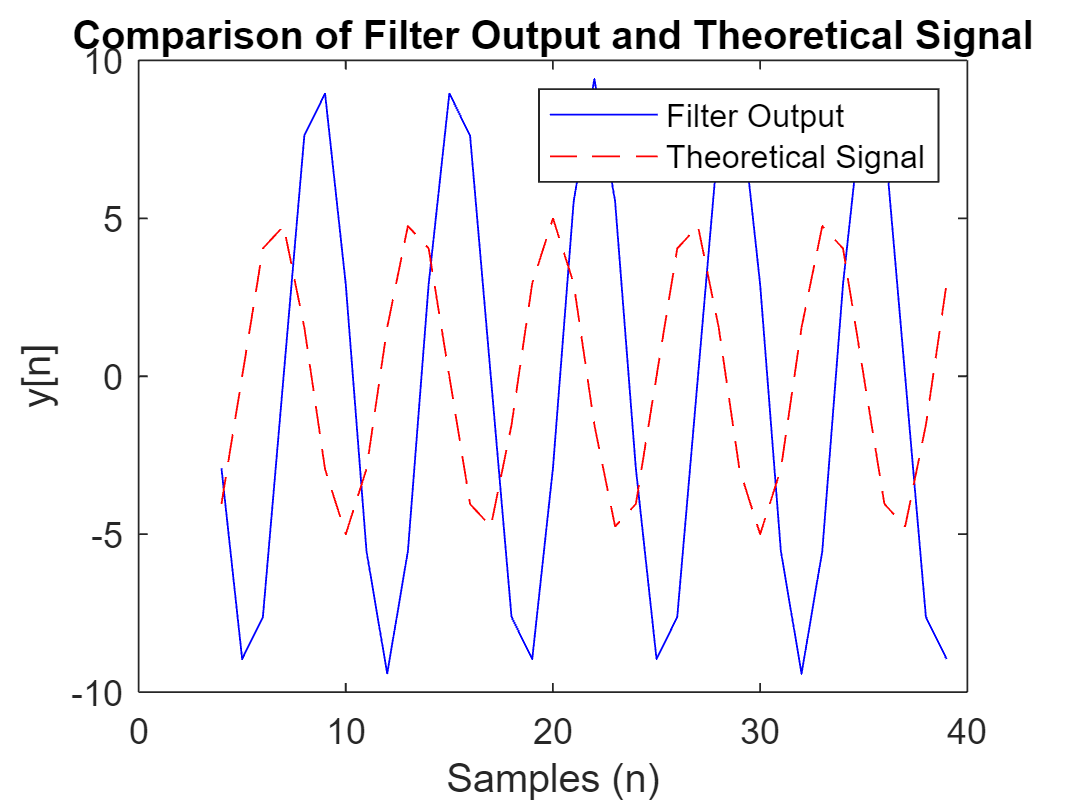


%e. Plot theoretical Signal and Compare with Output signal
y_theoretical = 5*cos(0.3*pi*n);
figure;
plot(n(5:40), y2(5:40), 'b', n(5:40), y_theoretical(5:40), 'r--');
title('Comparison of Filter Output and Theoretical Signal');
xlabel('Samples (n)');
ylabel('y[n]');
legend('Filter Output', 'Theoretical Signal');